# Optimization of the multiple feeding trajectory

**Manipulated variables**

- `u1 = Q_Glc [L/h]`: Glucose feed rate

- `u2 = Q_Glc [L/h]`: Glutamine feed rate

**Measured disturbance**

- `none`

**State variables**

- `x1 = V [L]`: liquid volume in the reactor

- `x2 = Xv [cell/L]`: viable cell density

- `x3 = Xt [cell/L]`: total cell density 

- `x4 = Gl`c` [mM]`: Glucose concentration

- `x5 = Gln [mM]`: Glutamine concentration

- `x6 = Lac [mM]`: Lactate concentration

- `x7 = Amm [mM]`: Ammonia concentration

- `x8 = mAb_ext [mg/L]`: extracellular mAb concentration

- `x9 = V_Glc [L]`: Cumulative feed volume of glucose

- `x10 = V_Gln [L]`: Cumulative feed volume of glutamine

**Output variables: the same as the state variables**

**The goal: **to maximize the final mAb mass (`x1(Tf)*x8(Tf)`). 

**Contraints:** 

- Upper bound on the feed volume of glucose (x9) 

- Upper bound on the feed volume of glutamine (x10)

## Specify the initial states.

V0 = 0.8;       % [L]
Xv0 = 2E+8;     % [cell]
Xt0 = 2E+8;     % [cell]
Glc0 = 25;      % [mM]
Gln0 = 4;       % [mM]
Lac0 = 0;       % [mM]
Amm0 = 0;       % [mM]
mAb_ext0 = 0;   % [mg/L]
V_Glc0 = 0;     % [L] total fed Glc volume
V_Gln0 = 0;     % [L] total fed Gln volume

x0 = [V0; Xv0; Xt0; Glc0; Gln0; Lac0; Amm0; mAb_ext0; V_Glc0; V_Gln0];

Specify the nominal inputs.

u0 = [0;0];

## Design nonlinear MPC with the true model

Create a nonlinear MPC object with 16 states, 16 outputs, 2 manipulated variables, and NO measured disturbance.

nx = 10;
ny = nx;
nu = 2;
nlmpcTrue = nlmpc(nx,ny,nu); % nlpmc object

標準のコスト関数では、MV が OV より少ないため、既定で 1 つ以上の OV に 0 の重みが割り当てられます。


Given the expected batch duration `Tf`, choose the controller sample time `Ts` and prediction horizon.

Tf = 240;   % [h] process duration
Ts = 12;    % [h] prediction model sample time
N = Tf/Ts;  % [step] prediction horizon
nlmpcTrue.Ts = Ts;
nlmpcTrue.PredictionHorizon = N;
% nlmpcobj.ControlHorizon = N;
nlmpcTrue.ControlHorizon = (48/Ts)*ones(5,1);
nlmpcTrue.Optimization.MVInterpolationOrder = 1;

### Specify the nonlinear state function in the controller

The function `discretizeStateFcn` converts the continuous-time model to discrete time using a multi-step Forward Euler integration formula.

STATEFCN = @deTremblay1992MFStateFcn;
nlmpcTrue.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcTrue.Model.OutputFcn = @(x,u) x;

% the nonlinear state function is for discrete-time models.
nlmpcTrue.Model.IsContinuousTime = false;

### Specify the bounds for input/output variables

Specify the bounds for a manipurated input variable (feed rate`)`.

% states
stateName = {'V','Xv','Xt','Glc','Gln','Lac','Amm','mAb_ext','V_Glc','V_Gln'};
stateUnit = {'L', 'cell/L', 'cell/L', 'mM', 'mM', 'mM', 'mM', 'mg/L','L','L'};
stateScaleFactor = [1.2 1.5E+9 1.5E+9 25 4 30 3 150 0.6 0.6];

for stateIdx = 1:nx
    nlmpcTrue.States(stateIdx).Name = stateName{stateIdx};
    nlmpcTrue.States(stateIdx).ScaleFactor = stateScaleFactor(stateIdx);
    nlmpcTrue.States(stateIdx).Units = stateUnit{stateIdx};
    % nlmpcTrue.States(stateIdx).Min = 0;
end

% manipulated variable
inputName = {'Q_Glc' 'Q_Gln'};

for inputIdx = 1:nu
    nlmpcTrue.MV(inputIdx).Name = inputName{inputIdx};
    nlmpcTrue.MV(inputIdx).ScaleFactor = 2.5/Tf;
    nlmpcTrue.MV(inputIdx).Units = 'L/h';
    nlmpcTrue.MV(inputIdx).Min = 0;
    nlmpcTrue.MV(inputIdx).MinECR = 0;
end

% output variables
for outputIdx = 1:ny
    nlmpcTrue.OV(outputIdx).Name = nlmpcTrue.States(outputIdx).Name;
    nlmpcTrue.OV(outputIdx).ScaleFactor = nlmpcTrue.States(outputIdx).ScaleFactor;
    nlmpcTrue.OV(outputIdx).Units = nlmpcTrue.States(outputIdx).Units;
    nlmpcTrue.OV(outputIdx).Min = 0;
    nlmpcTrue.OV(outputIdx).MinECR = 1;
end

### Specify the custom cost function

nlmpcTrue.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,1)*X(end,8) + 0.1) + 1E+6*e^2;
nlmpcTrue.Optimization.ReplaceStandardCost = true;

nlmpcTrue.Optimization.CustomIneqConFcn = @(X,U,e,data) [X(end,9) - 0.6 - e; X(end,10) - 0.6 - e];

### Specify the solver option

nlmpcTrue.Optimization.SolverOptions.Display = 'iter-detailed';
nlmpcTrue.Optimization.SolverOptions.Algorithm = 'sqp';

### Validate the nlmpc object

validateFcns(nlmpcTrue, x0, u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
Optimization.CustomIneqConFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


### Specify the initial guess of the feeding trajectory.

Specify the constant feed rate and the resulting state trajectory to be the initial guess of the optimization.

STATEFCN = @deTremblay1992MFStateFcn;
u_const = 2/Tf*[0.5;0.5];
[~,X0] = simConstantFeed(Ts,N,STATEFCN,x0,u_const); 

Final liquid volume: 2.8 L
Final mAb conc: 141.036 mg/L
Final mAb amount: 394.901 mg


options = nlmpcmoveopt;
options.MV0 = u_const';
options.X0 = X0(2:end,:);

## Off-line optimization of the feeding trajectory

Find the optimal trajectories for the manipulated variables such that final mAb mass is maximized. To do so, use the `nlmpcmove` function.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:55:32

tic
[~,~,Info_true] = nlmpcmove(nlmpcTrue,x0,u0,[],[],options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    2.531639e-03     4.000e-01     1.000e+00     0.000e+00     2.692e-03  
    1          37    2.535980e-03     4.000e-01     5.412e-06     2.125e-06     4.167e+00  
    2          39    3.411104e-03     3.504e-02     1.000e+00     2.247e+00     1.456e+00  
    3          41    3.437143e-03     3.467e-03     1.000e+00     2.751e-01     4.650e-01  
    4          43    3.455118e-03     6.506e-05     1.000e+00     1.273e-02     6.308e-02  
    5          45    3.455333e-03     2.891e-08     1.000e+00     3.411e-04     2.728e-03  
    6          47    3.455060e-03     5.613e-08     1.000e+00     1.016e-03     2.757e-02  
    7          49    3.453698e-03     1.381e-06     1.000e+00     5.074e-03     2.757e-02  
    8          51    3.446986e-03     3.392e-05     1.000e+00     2.521e-02     2.

Info_true = フィールドをもつ struct :
         MVopt: [21×2 double]
          Xopt: [21×10 double]
          Yopt: [21×10 double]
          Topt: [21×1 double]
         Slack: 1.6048e-09
      ExitFlag: 1
    Iterations: 152
          Cost: 0.0032


toc

経過時間は 34.403254 秒です。


printFinalmAb(Info_true);

Final liquid volume: 2 L
Final mAb conc: 155.14 mg/L
Final mAb amount: 310.28 mg


## Simulate the optimized feeding trajectory

The discretized model, which the nonlinear MPC has uses a simple Euler integration, which could be inaccurate. To check this, integrate the true model using the `ode15s` command for the optimized feeding trajectory. 

Final liquid volume: 2 L
Final mAb conc: 155.237 mg/L
Final mAb amount: 310.474 mg


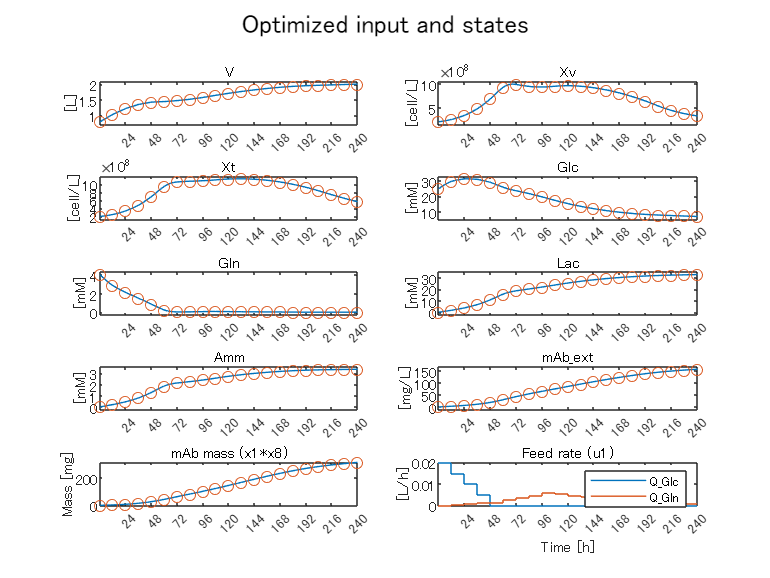

simTrueMFModel(Info_true,Ts,x0);

## Plant-model mismatch disturbs off-line optimization

Specify the model with intentinally errored parameter values to a new nlmpc object.

nlmpcError = nlmpcTrue;
STATEFCN = @deTremblay1992MFStateFcnError;
nlmpcError.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcError.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,1)*X(end,8) + 0.1) + 1E+6*e^2;
validateFcns(nlmpcError, x0, u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
Optimization.CustomIneqConFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


### Specify the initial guess of the feeding trajectory.

Specify the constant feed rate and the resulting state trajectory to be the initial guess of the optimization.

STATEFCN = @deTremblay1992MFStateFcnError;
u_const = 2/Tf*[0.5;0.5];
[~,X0_error] = simConstantFeed(Ts,N,STATEFCN,x0,u_const); 

Final liquid volume: 2.8 L
Final mAb conc: 54.792 mg/L
Final mAb amount: 153.418 mg


options_error = nlmpcmoveopt;
options_error.MV0 = u_const';
options_error.X0 = X0_error(2:end,:);

Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:56:08

tic
[~,~,Info_error] = nlmpcmove(nlmpcError,x0,u0,[],[],options_error)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    6.513908e-03     4.000e-01     1.000e+00     0.000e+00     1.782e-02  
    1          37    6.518254e-03     4.000e-01     5.412e-06     2.131e-06     4.169e+00  
    2          39    9.274776e-03     2.661e-02     1.000e+00     2.219e+00     6.423e-01  
    3          41    9.138946e-03     1.514e-03     1.000e+00     1.093e-01     4.632e-02  
    4          43    9.133036e-03     2.561e-06     1.000e+00     3.229e-03     1.953e-02  
    5          45    9.131252e-03     2.564e-07     1.000e+00     1.478e-03     1.482e-02  
    6          47    9.123544e-03     4.926e-06     1.000e+00     6.362e-03     1.597e-02  
    7          49    9.115442e-03     6.862e-06     1.000e+00     7.195e-03     1.205e-03  
    8          52    9.075009e-03     2.022e-06     1.000e+00     3.595e-02     9.

Info_error = フィールドをもつ struct :
         MVopt: [21×2 double]
          Xopt: [21×10 double]
          Yopt: [21×10 double]
          Topt: [21×1 double]
         Slack: 4.0055e-09
      ExitFlag: 1
    Iterations: 90
          Cost: 0.0068


toc

経過時間は 20.334744 秒です。


printFinalmAb(Info_error);

Final liquid volume: 2 L
Final mAb conc: 73.7474 mg/L
Final mAb amount: 147.495 mg


Simulate the true model with the feeding trajectory optimized in the presense of the plant-model mismatch.

Final liquid volume: 2 L
Final mAb conc: 143.09 mg/L
Final mAb amount: 286.18 mg


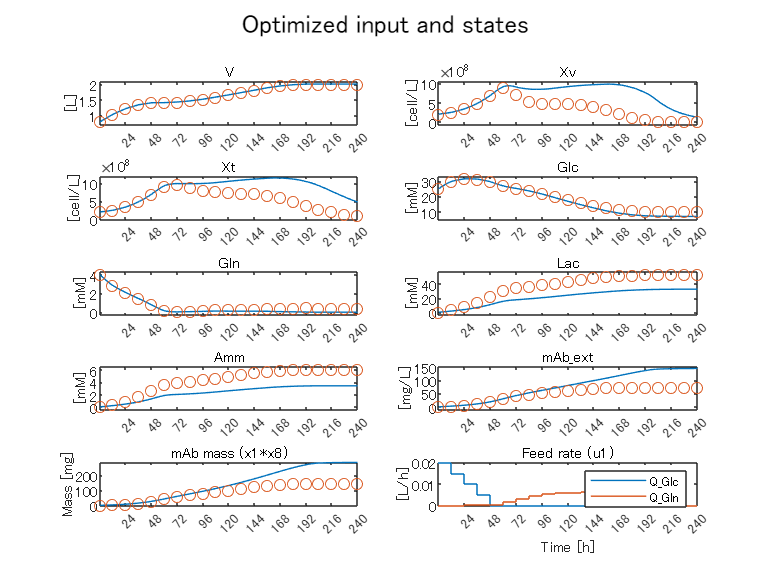

simTrueMFModel(Info_error,Ts,x0);

## On-line reoptimization in the presence of the plant-model mismatch

nlmpcClosedLoop = nlmpcError;
STATEFCN = @deTremblay1992MFStateFcnError;
nlmpcClosedLoop.Model.StateFcn = @(x,u,N) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcClosedLoop.Model.NumberOfParameters = 1;
nlmpcClosedLoop.Model.OutputFcn = @(x,u,N) x;
nlmpcClosedLoop.Optimization.CustomCostFcn = @(X,U,e,data,N) 1/(X(1+N,1)*X(1+N,8) + 0.1) + 1E+6*e^2;
nlmpcClosedLoop.Optimization.CustomIneqConFcn = @(X,U,e,data,N) [X(1+N,9) - 0.6 - e; X(1+N,10) - 0.6 - e];

validateFcns(nlmpcClosedLoop, x0, u0, [], {N});

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
Optimization.CustomIneqConFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Open the Simulink model.

mdl = 'MPC_multiFeed';
open_system(mdl)

To use the optional parameter in the prediction model, the model has a Simulink Bus block connected to the `params` input port of the Nonlinear MPC Controller block. To configure this bus block to use the `N` parameter, create a Bus object in the MATLAB workspace, and configure the Bus Creator block to use this object. Name the Bus object `'myBusObject'`.

createParameterBus(nlmpcClosedLoop,[mdl '/Nonlinear MPC'],'myBusObject',{N});

Simulink バス オブジェクト "myBusObject" が MATLAB ワークスペースで作成され、Bus Creator ブロック "MPC_multiFeed/Nonlinear MPC" がこのオブジェクトを使用するように構成されています。


timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:56:42

tic
simout = sim(mdl);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    6.775307e-03     1.000e-01     1.000e+00     0.000e+00     1.377e-02  
    1           9    1.344124e-01     8.824e-02     1.176e-01     4.695e-02     7.145e+02  
    2          11    6.807449e-03     5.575e-03     1.000e+00     3.523e-01     9.521e-02  
    3          13    6.816812e-03     2.091e-05     1.000e+00     1.305e-02     7.004e-02  
    4          15    6.816343e-03     1.536e-09     1.000e+00     8.030e-04     4.206e-02  
    5          17    6.813870e-03     3.228e-08     1.000e+00     3.130e-03     3.296e-02  
    6          19    6.813180e-03     2.268e-08     1.000e+00     1.218e-03     1.292e-03  
    7          21    6.812635e-03     1.000e-06     1.000e+00     1.162e-03     4.943e-03  
    8          23    6.812084e-03     1.000e-06     1.000e+00     1.249e-03     4.

toc

経過時間は 206.531565 秒です。


Final liquid volume: 2 L
Final mAb conc: 152.254 mg/L
Final mAb amount: 304.509 mg


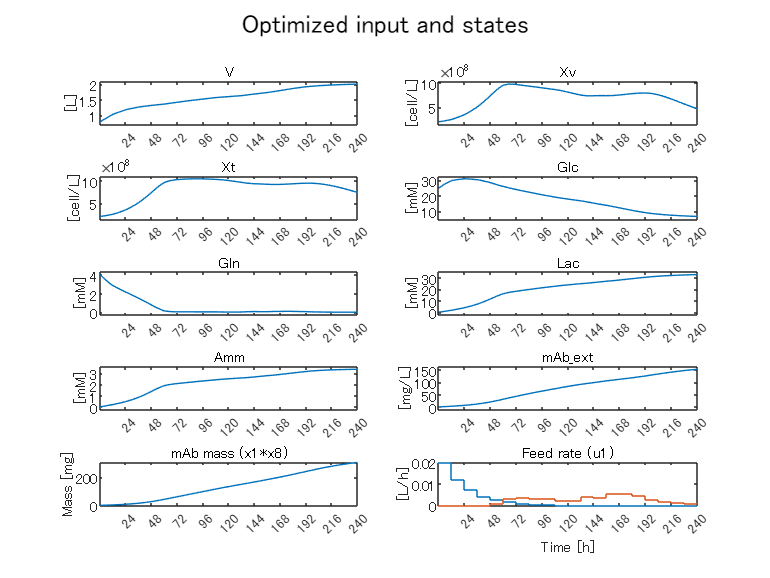

plotSimulinkLog(simout);